% nějaký jako zaokrouhlení nebo co

B = fir1(20,0.25);
WL = 4; % delka datoveho slova
FL = 3; % delka datove casti, prvni bit je znamenko
q = quantizer('mode','fixed','RoundMode','Nearest','format',[WL,FL]);
Bn = (1-2^-(FL))/max(B)*B % maximální číslo které tam jde uložit/ maximum z B

Bn =     0.0089    0.0090   -0.0000   -0.0303   -0.0739   -0.0851    0.0000    0.2128    0.5081    0.7700    0.8750    0.7700    0.5081    0.2128    0.0000   -0.0851   -0.0739   -0.0303   -0.0000    0.0090    0.0089


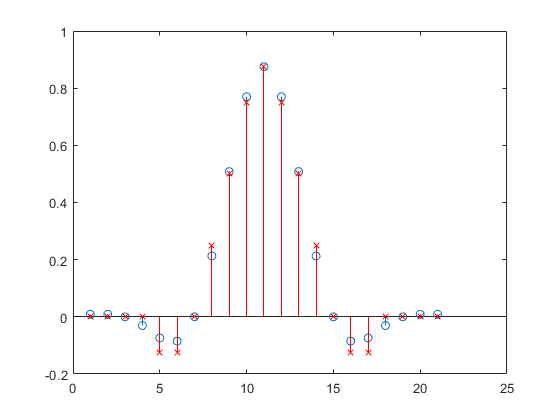

Bq = quantize(q,Bn); % zaokrouhlené

figure()
stem(Bn);
hold on;
stem(Bq,'xr'); % zaokrouhlené

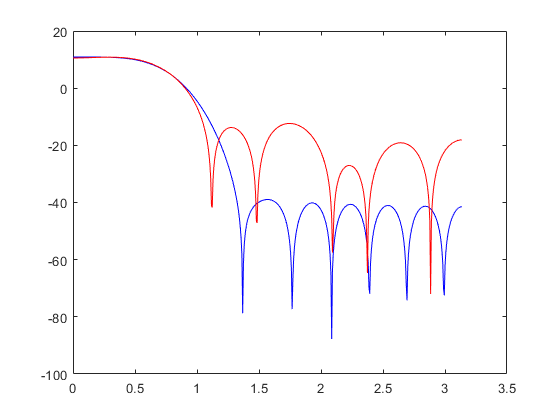


[H,W]= freqz(Bn);
[Hq,Wq]= freqz(Bq);
figure();
clf;

plot(W,20*log10(abs(H)),'-b'); % nějaká jako frekvenční charky
hold on;
plot(Wq,20*log10(abs(Hq)),'-r');

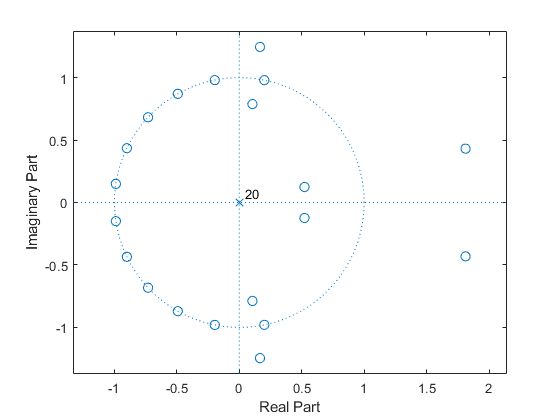



figure()
zplane(Bn);

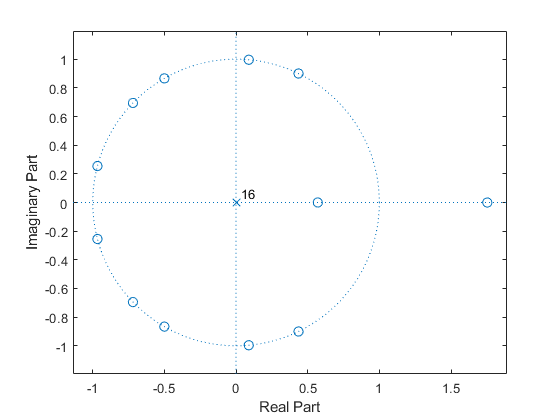

figure()
zplane(Bq);